folderPath = 'C:\Users\vithj\OneDrive\Documents\Visual Studio Code\AI ML\cw-data-cat\U01'; 

if ~isfolder(folderPath)
    error('The specified folder does not exist: %s', folderPath);
end

fileList = dir(fullfile(folderPath, '*.mat'));  

if isempty(fileList)
    error('No .mat files found in the specified folder: %s', folderPath);
end

fileNames = {fileList.name};  
nFiles = numel(fileNames);    

disp('List of .mat files found for User 01:');

List of .mat files found for User 01:


disp(fileNames);

    {'U04_Acc_FreqD_FDay.mat'}    {'U04_Acc_FreqD_MDay.mat'}    {'U04_Acc_TimeD_FDay.mat'}    {'U04_Acc_TimeD_FreqD_FDay.mat'}    {'U04_Acc_TimeD_FreqD_MDay.mat'}    {'U04_Acc_TimeD_MDay.mat'}



Processing file: U04_Acc_FreqD_FDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: 0.000007


Maximum value: 1.030704


Mean value: 0.168154


Standard deviation: 0.301865


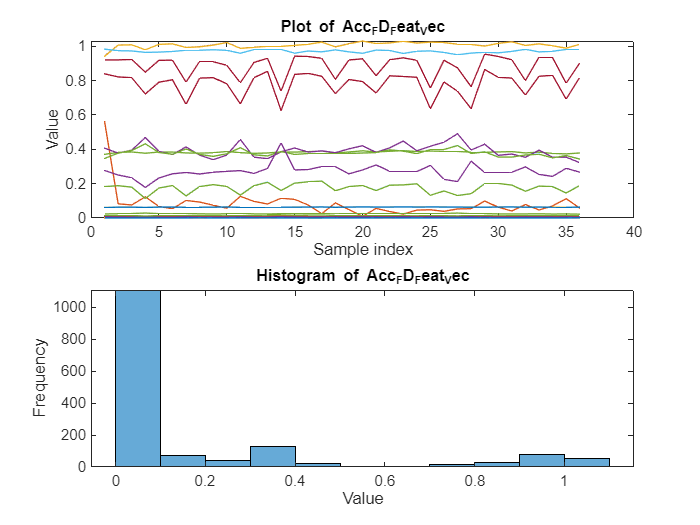

Processing file: U04_Acc_FreqD_MDay.mat


Fields in the current file:


    {'Acc_FD_Feat_Vec'}



Analyzing field: Acc_FD_Feat_Vec


Minimum value: -0.091517


Maximum value: 1.079220


Mean value: 0.167100


Standard deviation: 0.304111


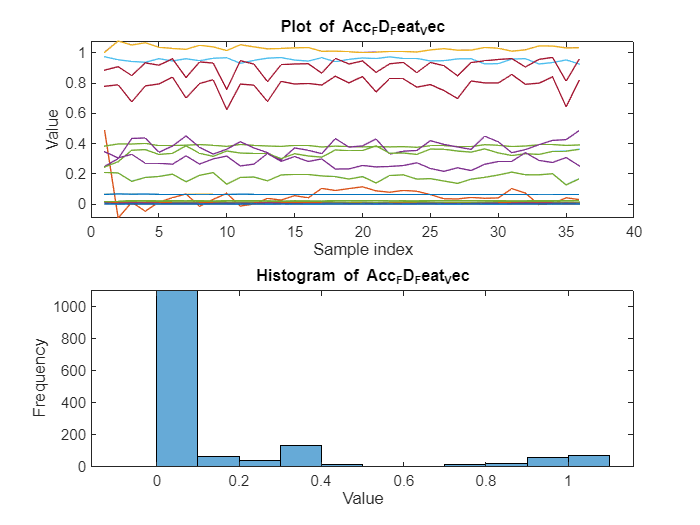

Processing file: U04_Acc_TimeD_FDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -2.323537


Maximum value: 241.000000


Mean value: 11.864938


Standard deviation: 36.335451


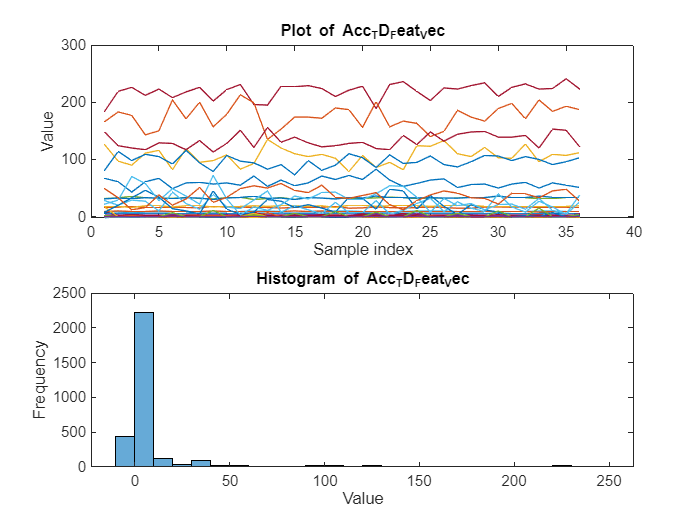

Processing file: U04_Acc_TimeD_FreqD_FDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -2.323537


Maximum value: 241.000000


Mean value: 8.025536


Standard deviation: 30.282133


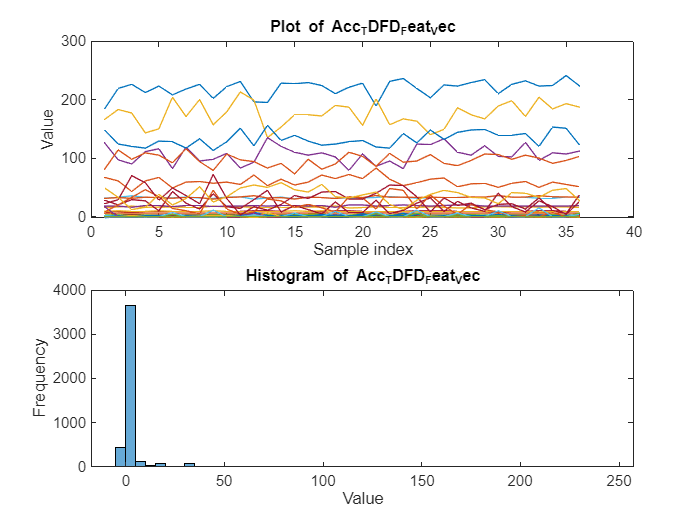

Processing file: U04_Acc_TimeD_FreqD_MDay.mat


Fields in the current file:


    {'Acc_TDFD_Feat_Vec'}



Analyzing field: Acc_TDFD_Feat_Vec


Minimum value: -2.595803


Maximum value: 235.000000


Mean value: 8.020742


Standard deviation: 29.251147


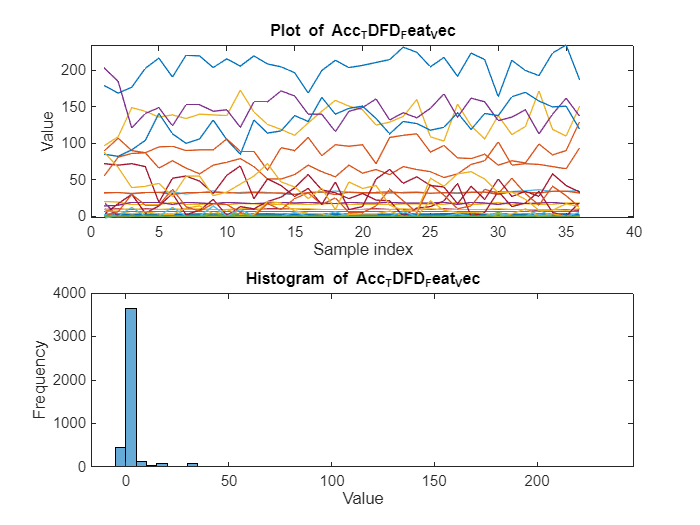

Processing file: U04_Acc_TimeD_MDay.mat


Fields in the current file:


    {'Acc_TD_Feat_Vec'}



Analyzing field: Acc_TD_Feat_Vec


Minimum value: -2.595803


Maximum value: 235.000000


Mean value: 11.858317


Standard deviation: 35.056071


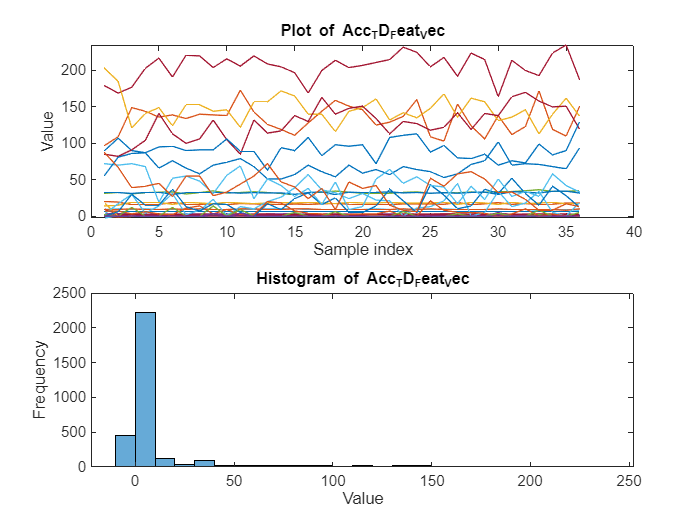


for i = 1:nFiles
    filePath = fullfile(folderPath, fileNames{i});
    
    if exist(filePath, 'file') == 2
        data = load(filePath);  
        fprintf('Processing file: %s\n', fileNames{i});
        
        fields = fieldnames(data);  
        
        disp('Fields in the current file:');
        disp(fields);
       
        for j = 1:length(fields)
            fieldData = data.(fields{j}); 
            
            fprintf('Analyzing field: %s\n', fields{j});
            fprintf('Minimum value: %f\n', min(fieldData(:)));
            fprintf('Maximum value: %f\n', max(fieldData(:)));
            fprintf('Mean value: %f\n', mean(fieldData(:)));
            fprintf('Standard deviation: %f\n', std(fieldData(:)));
            
            figure;  
            subplot(2, 1, 1); 
            plot(fieldData);  
            title(['Plot of ' fields{j}]);
            xlabel('Sample index');
            ylabel('Value');
            
            subplot(2, 1, 2);  
            histogram(fieldData); 
            title(['Histogram of ' fields{j}]);
            xlabel('Value');
            ylabel('Frequency');
        end
    else
        warning('File does not exist: %s', filePath);
    end
end